# 1. Motor Control using Model-Based Design

Model-based design refers to the development workflow, where one uses simluation models during the whole development cycle. These models are sometimes referred to as Digital Twins. To control our segway motors we start by building a digital model of the motors. We do this by assembling individual parametrizable Simscape blocks into a functional motor component and adjust the parameters to fit the real motors. The last step is crucial, because real parameters sometimes deviate from the specs given by the manufacturer.

## 1.1. Prework

The workflow in this script uses Simscape Electrical and Simscape Multibody. In case you are not familiar with it, please have a look at the corresponding online training.

- Simscape Electrical Onramp: [https://matlabacademy.mathworks.com/details/circuit-simulation-onramp/circuits](https://matlabacademy.mathworks.com/details/circuit-simulation-onramp/circuits)

- Simscape Multibody: [https://matlabacademy.mathworks.com/details/multibody-simulation-onramp/ormb](https://matlabacademy.mathworks.com/details/multibody-simulation-onramp/ormb)

## 1.1 Motor Model

The model should allow us to test the behavior of the component with respect to the input signal. In our case this is the speed response with respect to the PWM duty cycle signal. Sometimes it is not necessary to build a model from scratch. In our case, we are lucky and can make use of the following example [Control DC Motor with PWM Voltage source and H-Bridge Driver](https://www.mathworks.com/help/sps/ug/pwm-controlled-dc-motor.html) example. This model already reflects the electronic components on the Arduino board.

openExample('simscapeelectrical/PWMControlledDCMotorExample')

Since we like to use the motor model as an individual, reusable component we modify the example with the corresponding input and output ports. Furthermore, we add the gear components and an interface block to connect the Simscape rotational network (green) to the Simscape Multibody part that represents the wheel (brown). The color of the signal lines represents the Simscape domain (electric, rotational, multibody).

 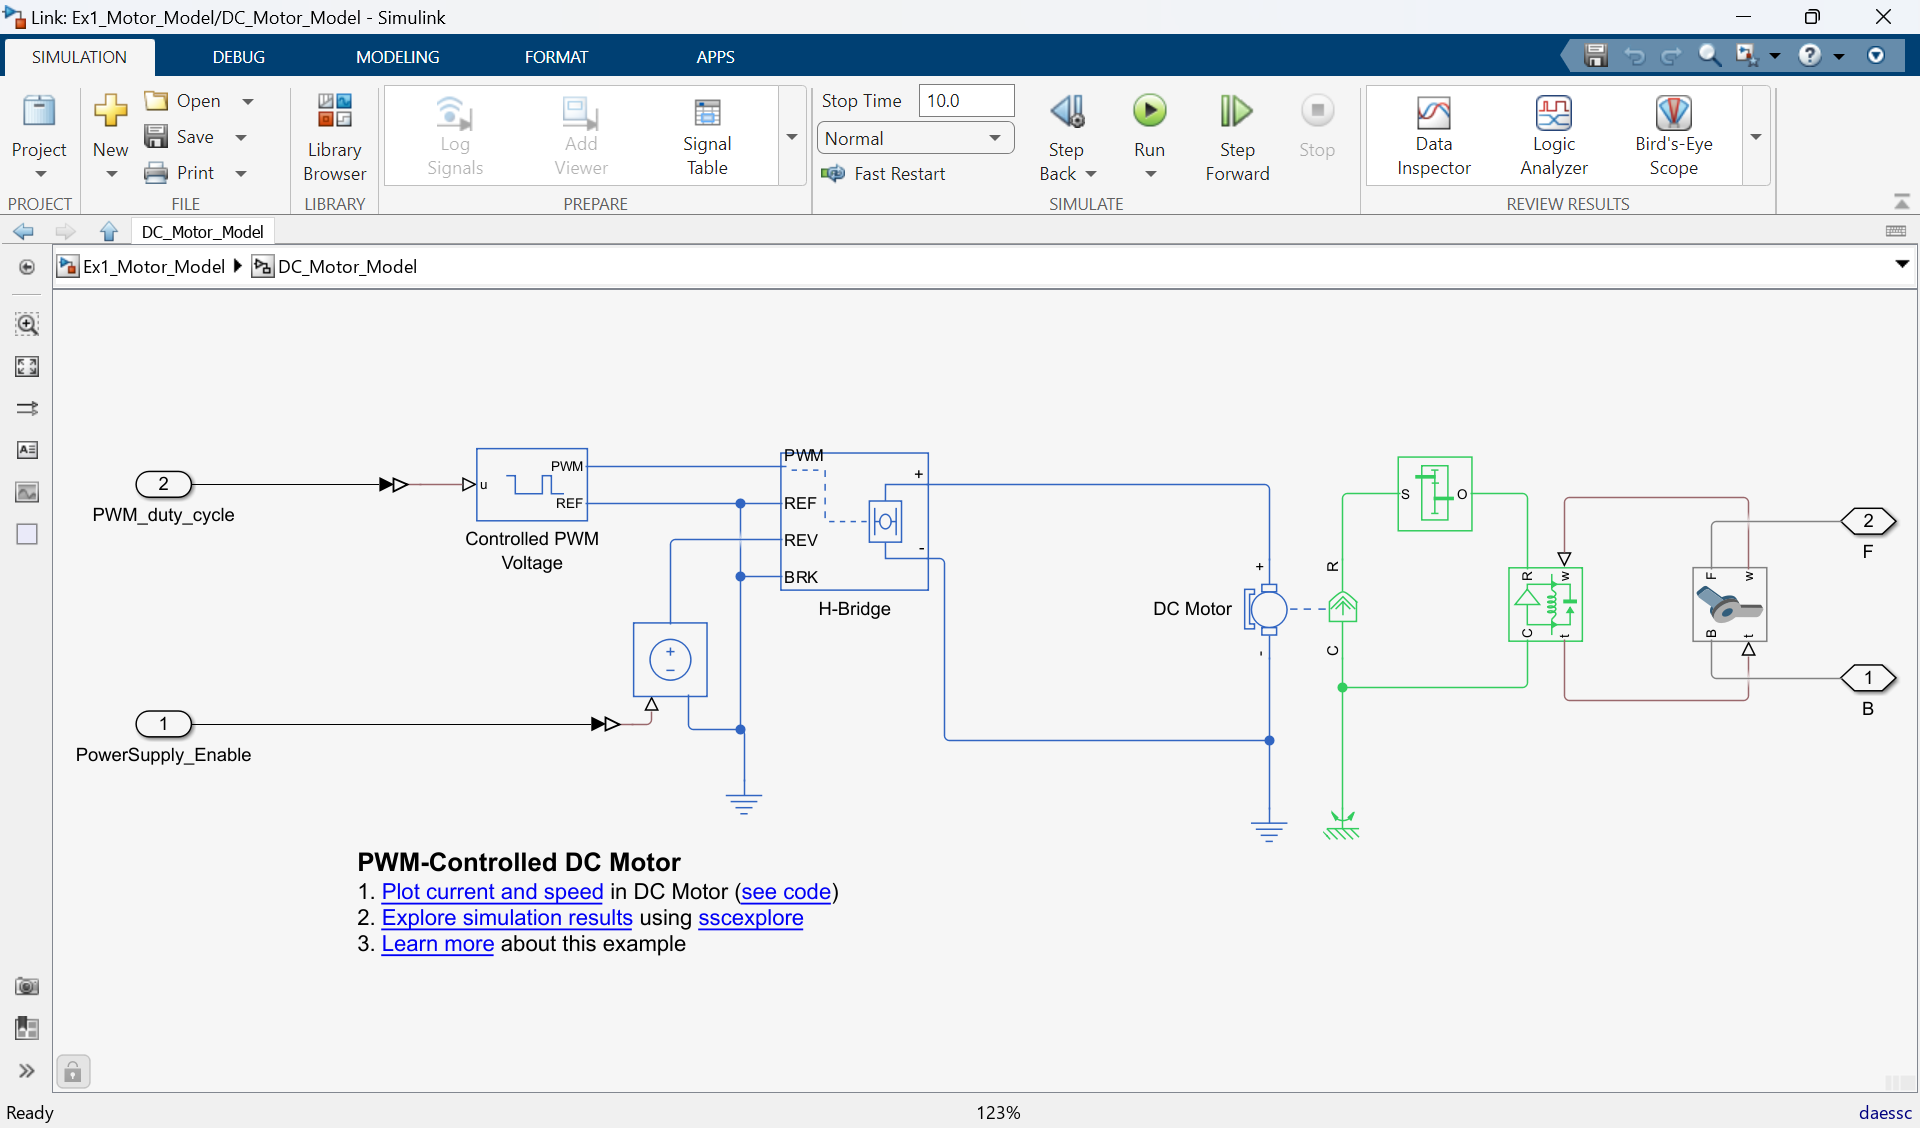

**Figure:** Motor model: The left (blue) part represents the electrical model of the motor including the H-Bridge. On the right side is the motor gear (green) and the interface to the Multibody model (brown).

For later use we save the model as a library block (see Libraries/SigiLib.slx).

To learn more about creating libraries you can consult the following resources:

- MATLAB Documentation: Create Custom Library: [https://www.mathworks.com/help/simulink/ug/creating-block-libraries.html](https://www.mathworks.com/help/simulink/ug/creating-block-libraries.html)

- Video “Libraries in Simulink made Easy” [https://www.youtube.com/watch?v=xWmIACn5Te0](https://www.youtube.com/watch?v=xWmIACn5Te0)

## 1.2 Definition of Model Parameters

Now that we have the motor model assembled we have to adjust the physical parameters to the real components. To do this, we can add the parameters from the specification sheet to the Simscape blocks. Double clicking on the DC motor block e.g. yields the following view:

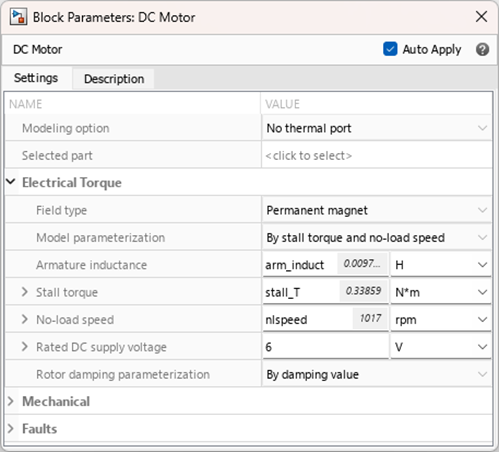

We can either add the numbers and units directly or add variable names. The second approach has the benefit that we can later tune these parameters more easily to match the real behavior. Additionally, if we use variables, we can link them to so-called model/subsystem masks. A mask is a custom interface for a block that hides the block content, making it appear as an atomic block with its own icon and parameter dialog box. It encapsulates the block logic, provides controlled access to the block data, and simplifies the graphical appearance of a model. When you mask a block, a mask definition is created and saved along with the block. A mask changes only the block interface, and not the underlying block characteristics. You can provide access to one or more underlying block parameters by defining corresponding mask parameters on the mask. A mask for the entire motor model might look as follows, whereby the fields for the values are linked to variables of the underlying model.

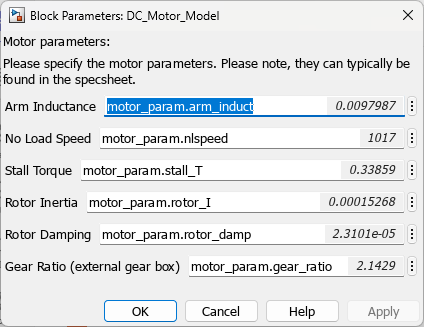

As mentioned, we saved the motor model as a library block. This is very useful, because we can now parametrize it for different variants using the block mask. This means, in case we decide to equip the robot with another motor, we can simply alter the corresponding mask parameters.

For sure these parameters have to be defined somewhere. To set the motor parameters we can use the [define_motor_parameters](matlab:open('..\Helpers\define_motor_parameters.m')) helper function. This function uses the information from the specs sheet and saves the motor parameters in a MATLAB structure in the workspace, which is then referrenced from within the Simulink model.

motor_param=define_motor_parameters("2");

Apart from this, we also have to define the gear ratio of the external gearbox as well as the wheel diameter.

motor_param.gear_ratio= 49/17;
motor_param.wheel_diameter=0.08;
 


## 1.3 Build Simscape Testbench and Model the Motor

To test the motor, we have to connect it with an input and then measure the output speed. Since the speed depends on the inertia of the attached wheel we integrate our model into a virtual testbench that containts a dummy representation of the wheel as well. The structure of our digital testbench then looks as shown below:

open("Ex1_Motor_Model.slx")

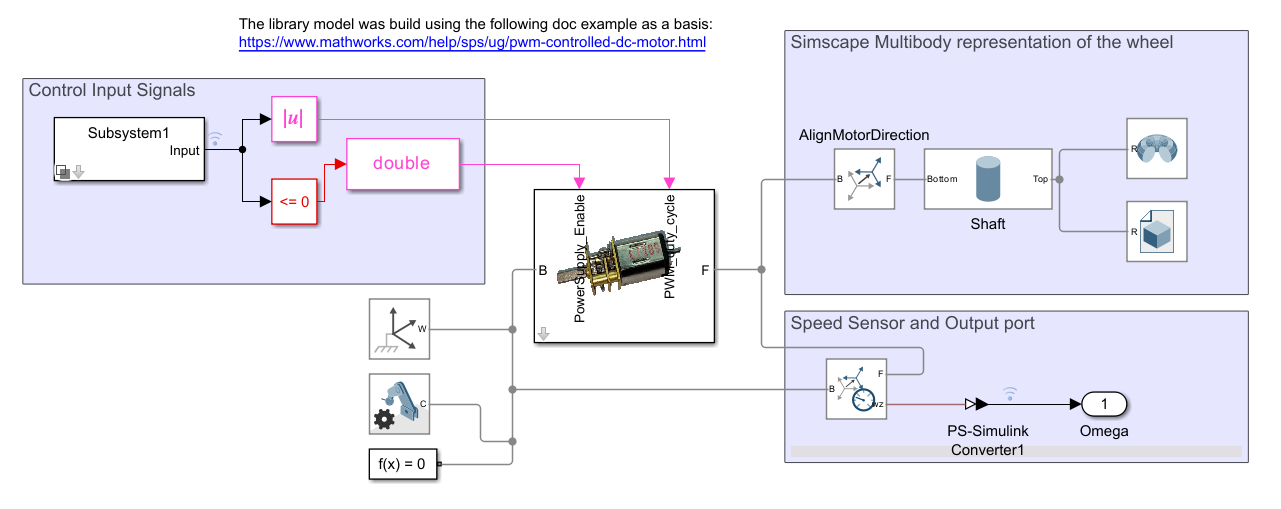

## 1.4 Simulate the Model

Now, we are ready to make a first test run of the motor model. The model is configured to drive the motor using a square-wave input signal for the PWM-duty cycle.

%open("Ex1_Motor_Model.slx")
out=sim("Ex1_Motor_Model")

out =   Simulink.SimulationOutput:

                logsout: [1x1 Simulink.SimulationData.Dataset] 
                 simlog: [1x1 simscape.logging.Node] 
                   tout: [2759x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Display the recorded data in a plot

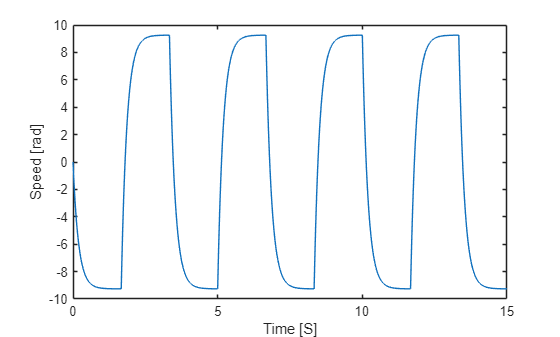

figure
omega_mod=out.yout{1}.Values.Data;
time_mod=out.yout{1}.Values.Time;
plot(time_mod,omega_mod)
ylabel("Speed [rad]");
xlabel("Time [S]")

## 1.5 Implement motor control for Arduino board (S functions)

Now that we have our motor model, we build a model that is able to connect to the Arduino board and drive the motors. As a prerequisite, we have to install the Simulink Support package using the add-on explorer. For more information about the Support package please visit: [https://www.mathworks.com/matlabcentral/fileexchange/40312-simulink-support-package-for-arduino-hardware](https://www.mathworks.com/matlabcentral/fileexchange/40312-simulink-support-package-for-arduino-hardware)

In case you have already done this, please skip the following subsection.

### 1.5.1 Install the Hardware support package

**Please note that the Arduino board used in this demo is a customized one that is based on the Arduino Leonardo. During the hardware setup you should thus select the Leonardo.**

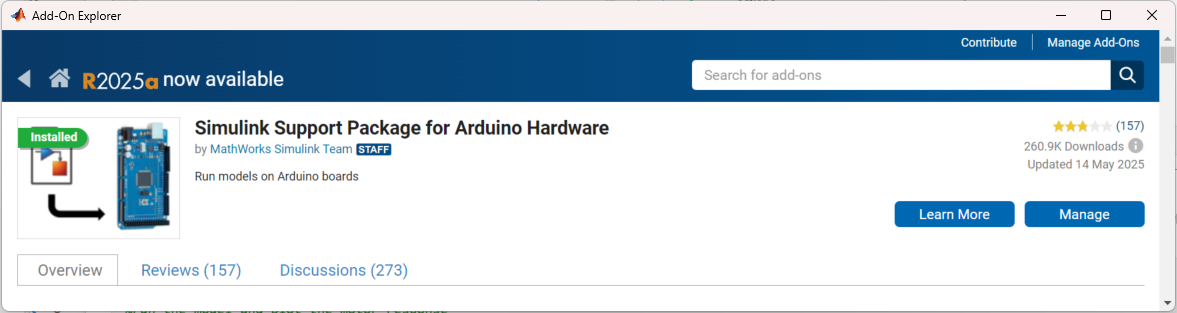

After the setup of the hardware board, you have the Arduino connected to your PC and should be ready to deploy models

### 1.5.2 I/O Connections with Motors

The Arduino boards has two motors with encoders. The motors are driven using a PWM signal with range [0 255]. This can be implemented by using the Simulink blocks provided by the Simulink Support Package for Arduino. To set the direction of the wheel, we have to send a boolean value to an additional pin on the board.

In summary we can drive each motor by addressing two output pins. To read the motor position we make use of the encoders. Unfortunately, the support package does not provide blocks for the encoders. To facilitate communication with them, we integrate code from an Arduino library using an S-function block. The S-function block serves as a wrapper for the C++ code from the Arduino library.

To convert the encoder signals to position values, we have to consider the gear box ratios and the encoder discretization. To facilitate reuse of the model, we specify these values in the mask of the "Encoder_conversion" subsystem.

The final model looks like this:

open("Ex2_MotorResponse.slx")

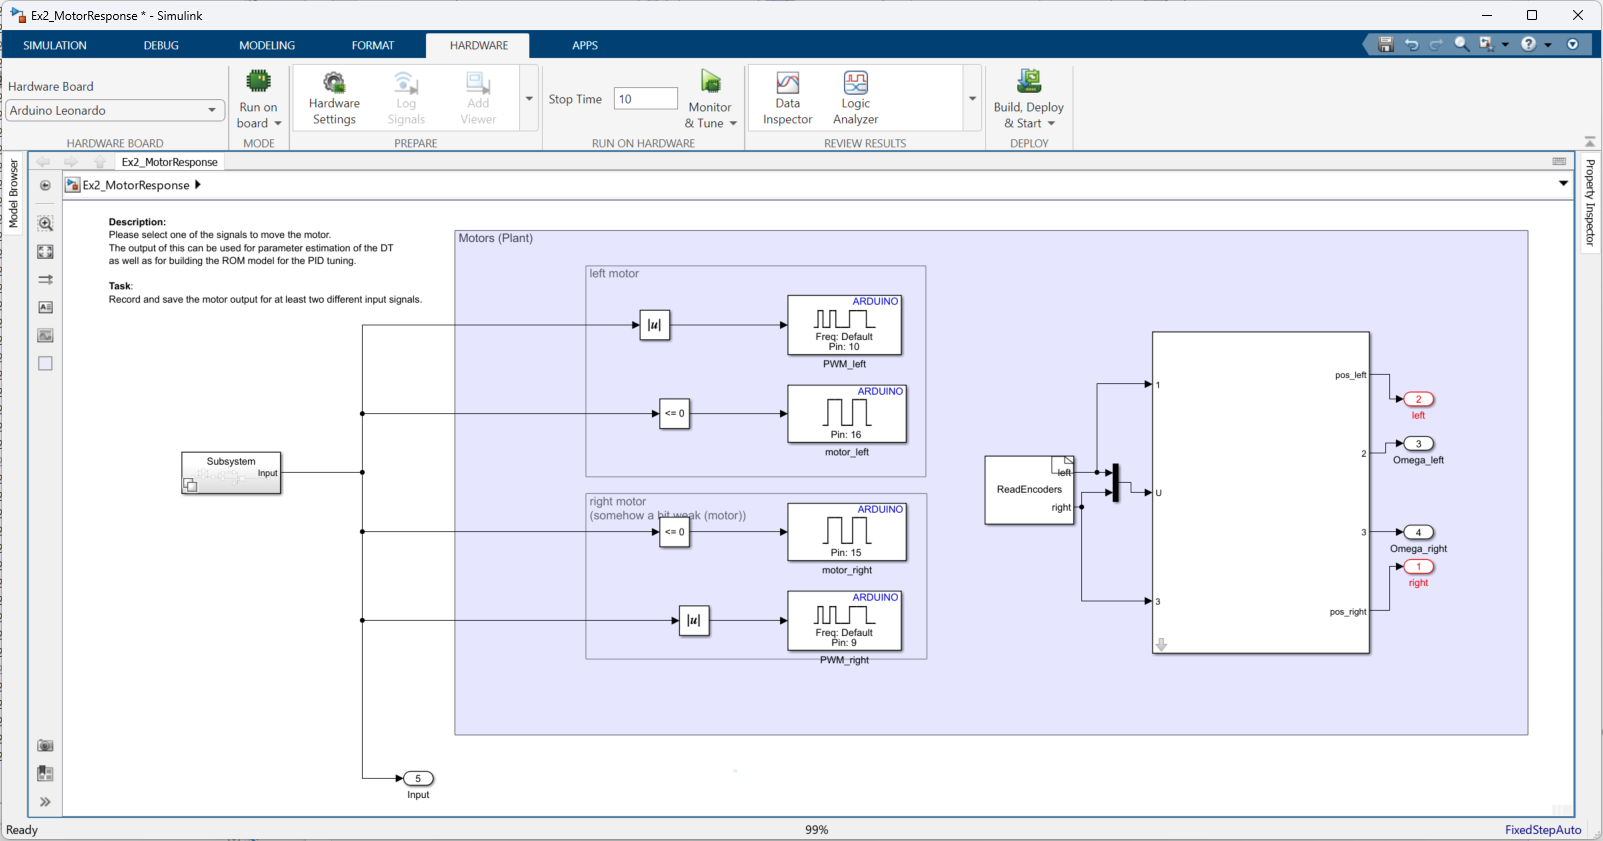

### 1.5.3 Prepare Robot for Run of Model

This model is now used to record the motor response from the real system. Before it is run, make sure that the hardware is:

- correctly connected,

- powered (blue LED is on),

- and that the Sigi is placed on the bumpers with the wheels facing upwards (see below).

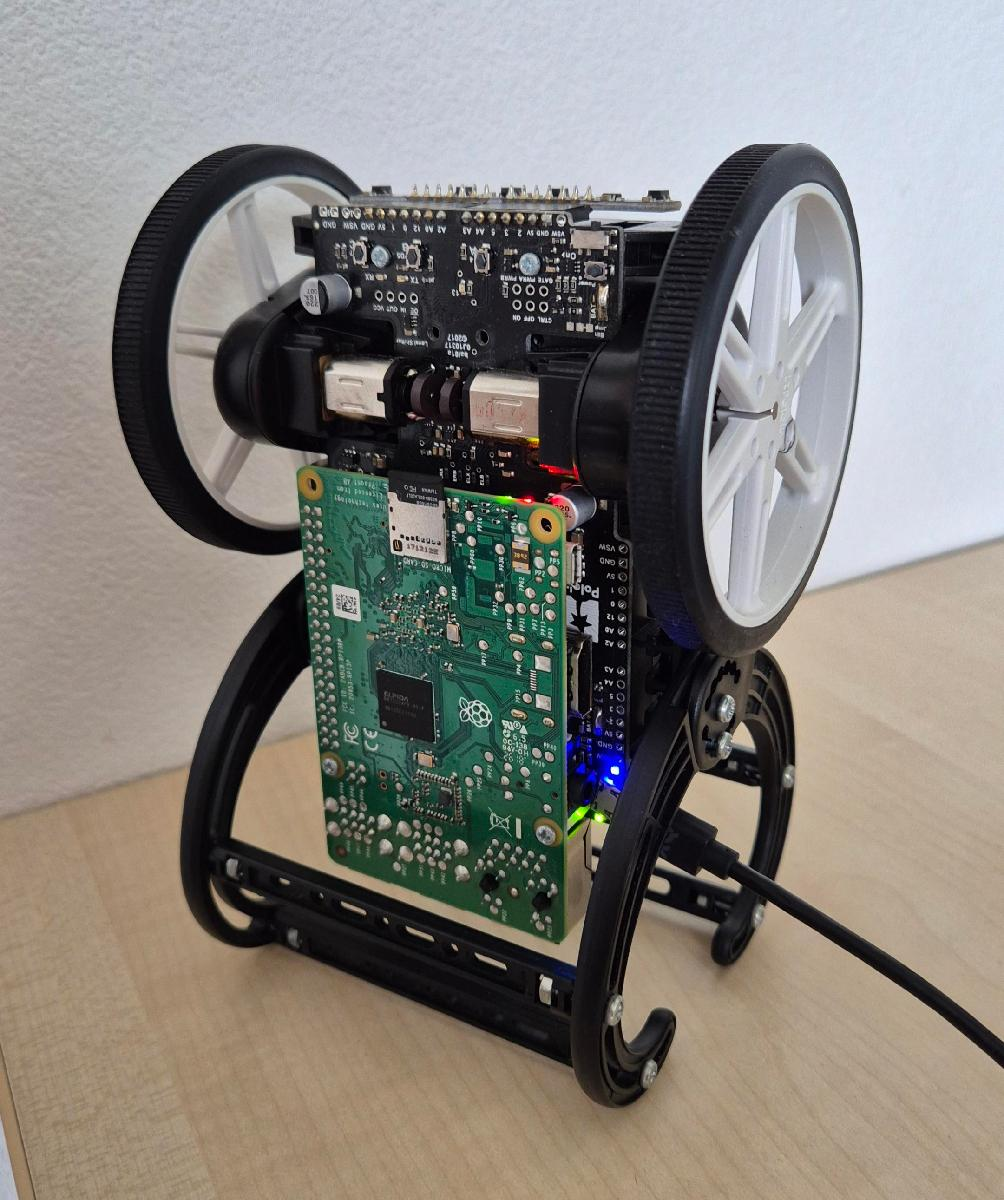

### 1.5.4 Run Model in External Mode

In order to run the model you have to configure the hardware settings in the model configuration. Please make sure that the COM ports are set correctly. It is known that the automatic detection of the port numbers might not work with this board. If you do not know the COM ports, please check your system tools such as the device manager on Windows. The configuration requires to set two ports. One of them is the bootloader port. In order to make this visible in the device manager you have to push the reset button on the upper right of the board twice. The port should then appear for about 15sec and the orange LED on the board should be blinking.

Once the setup is done you can run the model in external mode. This allows recording the position outputs into the workspace.

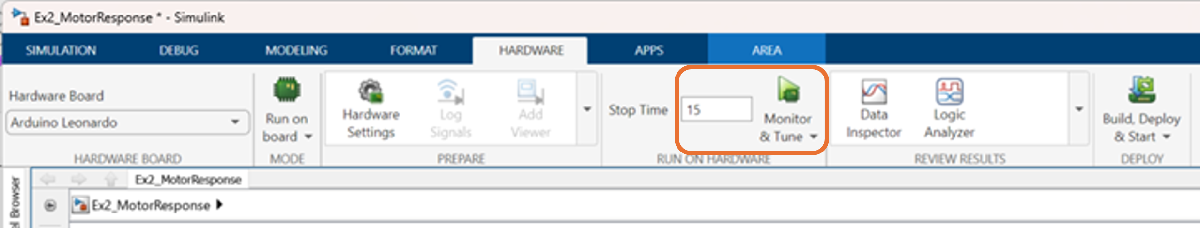

figure
plot(yout{3}.Values.Data) %left motor
hold on
plot(yout{4}.Values.Data) %right motor
plot(yout{5}.Values.Data) %PWM
legend({"left motor","right motor", "PWM"})
xlabel("Time [s]")
ylabel("Speed [rad]/ PWM output")

**Important note: this model outputs the position in radians and not centimeters! There is no reference to the wheel diameter in the model.**

After the model run terminated you can save the recorded data to the workspace.

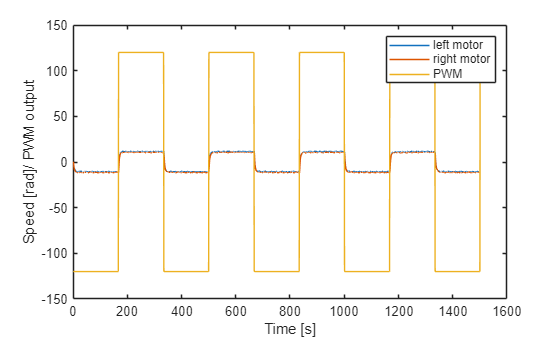

Input=double(yout{5}.Values.Data);
Input_t=double(yout{5}.Values.Time);
Omega_left_t=double(yout{3}.Values.Time);
Omega_left=double(yout{3}.Values.Data);
Omega_right_t=double(yout{4}.Values.Time);
Omega_right=double(yout{4}.Values.Data);

### 1.5.5 Sim2Real Gap

To evaluate the accuracy of our model, we can compare the experimental measurements with the results from the simulation. The difference in the two is called the Sim2Real gap. The smaller the discrepancy the better the model. Obviously there is still some room for improvement.

figure
plot(time_mod,omega_mod,Omega_left_t,Omega_left)
title("Sim to Real Gap")
legend("simulation", "reality")
ylabel("Omega [rad]")
xlabel("Time [s]")

## 1.6 Refine parameters of the Motor Twin using parameter estimation

We will now use a method called parameter estimation to find the appropriate model parameters. The workflow was adapted from the following doc example: [https://www.mathworks.com/help/sldo/ug/dc-servo-motor-parameter-estimation.html](https://www.mathworks.com/help/sldo/ug/dc-servo-motor-parameter-estimation.html).

% Modelling tasks:
% Put the two models together in a variant model block using references/libraries
% Run experiment with certain specified inputs (e.g. number of step functions) to measure the response of the motor (maybe have to check some initial boundaries for this...) and the model
%     Record the motor response with respect to a certain PWM signal. (note that this will depend on the status of the battery pack) -> PWM vs Speed Curve
% Use Parameter Estimator App to determine the parameters of the model.

The complete workflow can be done with the parameter estimator app.

spetool('Ex1_Motor_Model')

Once opened, create a new experiment.

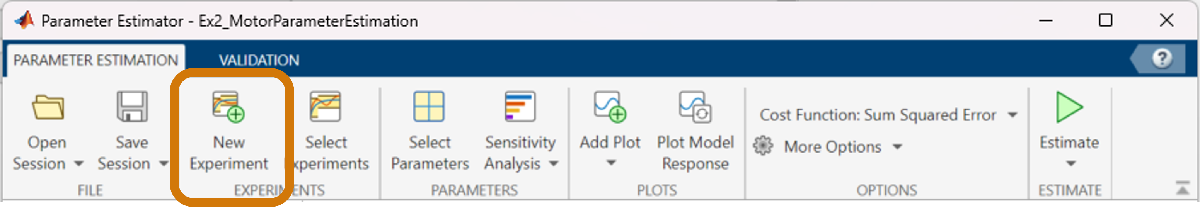

Then select the signals and configure the experimental data. When done, click on close.

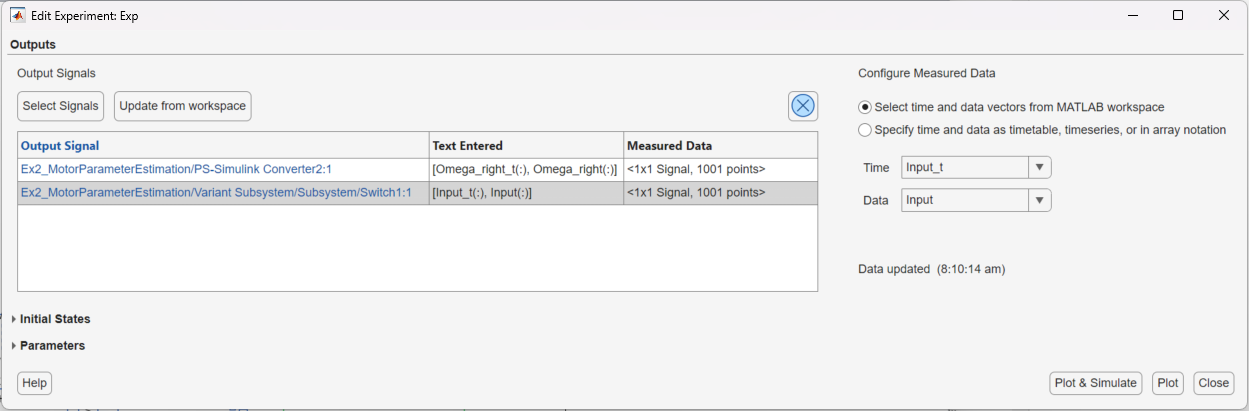

Back in the toolstrip, select parameters dialogue and click on select parameters:

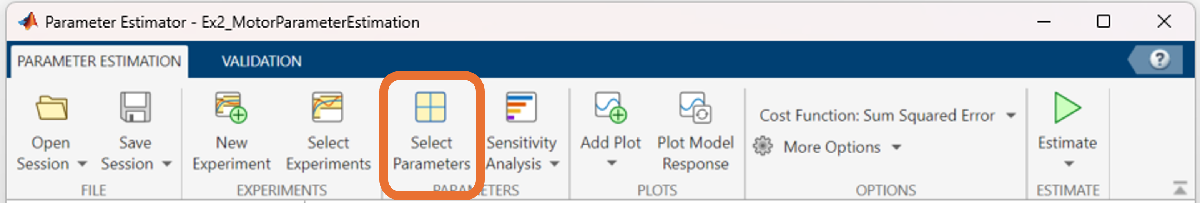

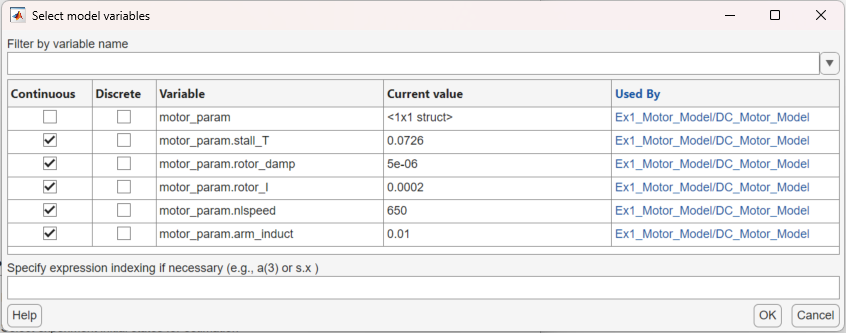

- enter the above variables manually using motor_param.varname

- Tick all the parameters as continuous. And confirm with OK.

- Set the correct bounds for the optimization -> i.e. set all lower bounds to 0. -> confirm with "close"

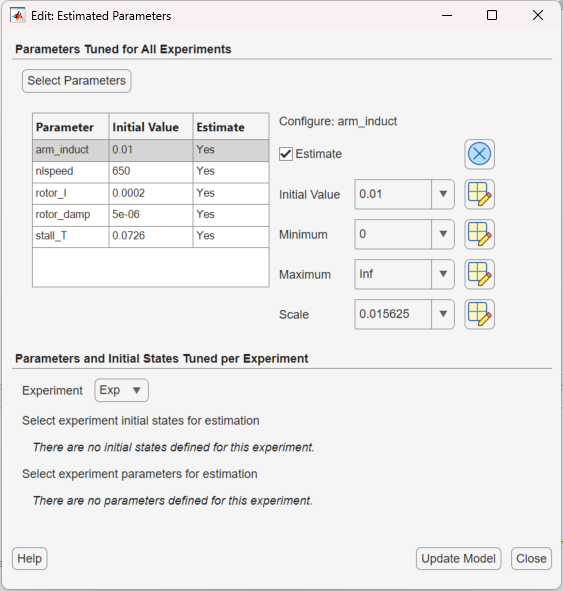

Run the optimization by clicking on "Estimate" in the toolstrip.

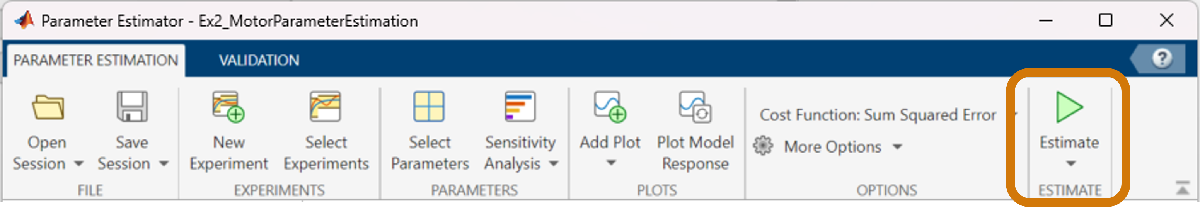

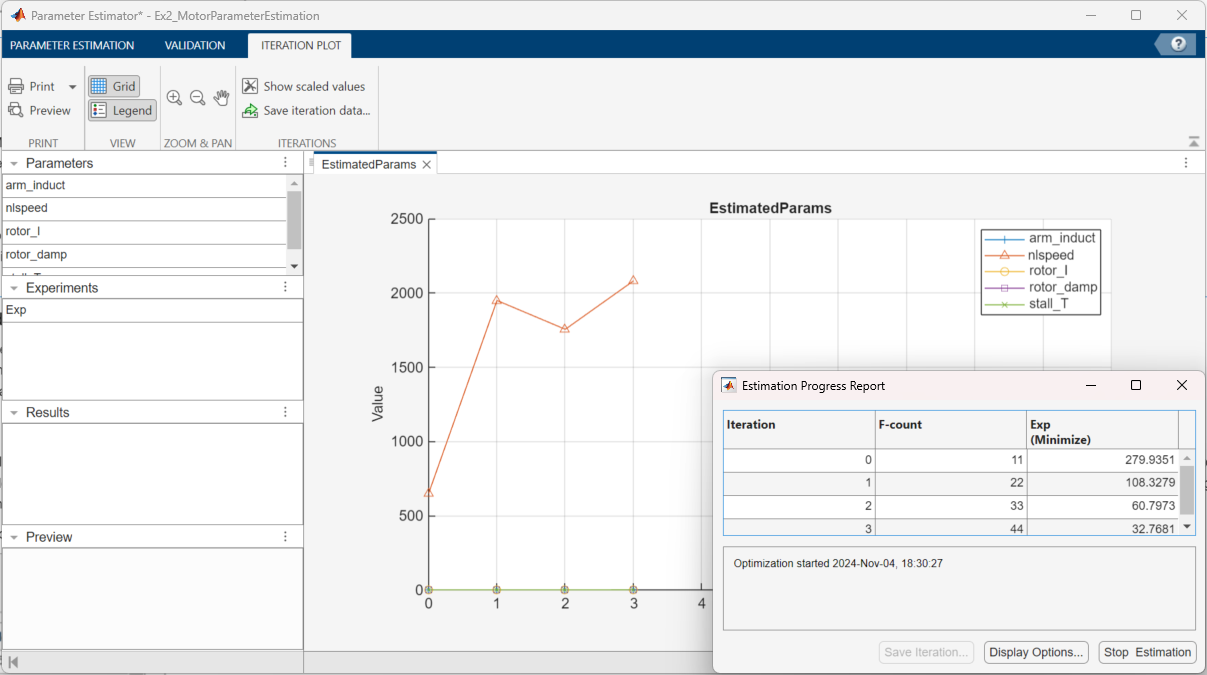

Compare the optimized parameters with the ones from the specs

motor_param

- Once the optimization finished, the adjusted parameters can be found in the MATLAB workspace. (it is advised that you check the parameters if they are reasonable)

- **Make a check to see if the optimization was successful! -> still to be implemented (run model and compare)**

- Save the optimized parameters to a .mat file for later use by selecting the side in the dropdown and running the section.

- Repeat the steps in 1.3 for the second motor.

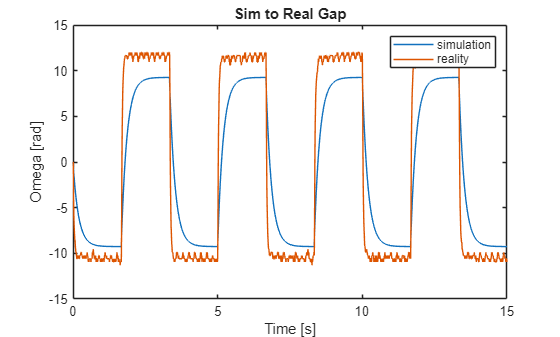


motor="right";

if motor=="left"
    save("./Work/optimized_param_mot_left.mat","motor_param",'-mat')
elseif motor=="right"
    save("./Work/optimized_param_mot_right.mat","motor_param",'-mat')
end

We now have successfully adjusted the parameters of our motor model to fit the real robot. In a next step we can design the controllers for the low level control of the motors.

## 1.7 Tune PID Controller using the Motor Model

As we have seen, motors do not always have exactly the same specifications. In order to get a well controlled output, we like to develop a simple closed loop control for the motor speed. Another reason why this is necessary is that the motor speed might depend on different parameters like motor temperature as well as external torque. Not having the desired output of the motor will complicate the implementation of a control algorithm for the balancing and position control of the robot. For this low-level control we use a simple PID controller. If you are not familiar with implementing controls in Simulink you can check the Simulink controls design onramp: [https://matlabacademy.mathworks.com/details/control-design-onramp-with-simulink/controls.](https://matlabacademy.mathworks.com/details/control-design-onramp-with-simulink/controls.)

For the implementation of the controller we built a new Simulink Model and did the following:

- Reuse the motor library block and load the parameters. Then add a control loop to the motor model

- Use a step function as input for the position setpoint. Use position signal as output.

- Optimize PID parameters of the digital twin model to satisfy a certain time constant (PID Optim App) (design requirement)

- Add an implementation of the deployment version to drive an individual motor as a variant subsystem ([https://www.mathworks.com/help/simulink/var/what-is-a-variant.html](https://www.mathworks.com/help/simulink/var/what-is-a-variant.html))

Please note that the two motors might be slightly different, implying that we have to tune the PID for each of them. To start with the tuning select the motor to be optimized.

motor="left";
% the following code will set the output pin parameters and reload the initial parameters
if motor=="left"
    load('optimized_param_mot_left.mat')
    motor_param.PWMpin=10;
    motor_param.Pin=16;
    motor_param.threshold=12;
elseif motor=="right"
    load('optimized_param_mot_right.mat')
    motor_param.PWMpin=9;
    motor_param.Pin=15;
    motor_param.threshold=33;
end

We can now use the Simscape model and adjust the PID controller with the PID tuner App to yield a time constant of* 0.1s.*

When starting the Simscape model, please make sure that the DT model is selected in the variant block. Also check that you have chosen the daessc variable step solver in the solver configuration. 

open("Ex3_PID_Tuning.slx") 

motor_param = struct with fields:
       motor_ratio: 51.4500
        arm_induct: 0.0067
           nlspeed: 767.2769
        rotor_damp: 3.1878e-06
           rotor_I: 1.9800e-04
           stall_T: 0.5020
                 P: 15
                 I: 400
                 D: 0
                 N: 100
        gear_ratio: 2.8824
    wheel_diameter: 0.0800


To open the PID Tuner App, double click on the PID block and select "Tune".

Then adjust the sliders, so that the PID satisfies your design requirements. Once done, update the PID block by clicking on "Update Block".

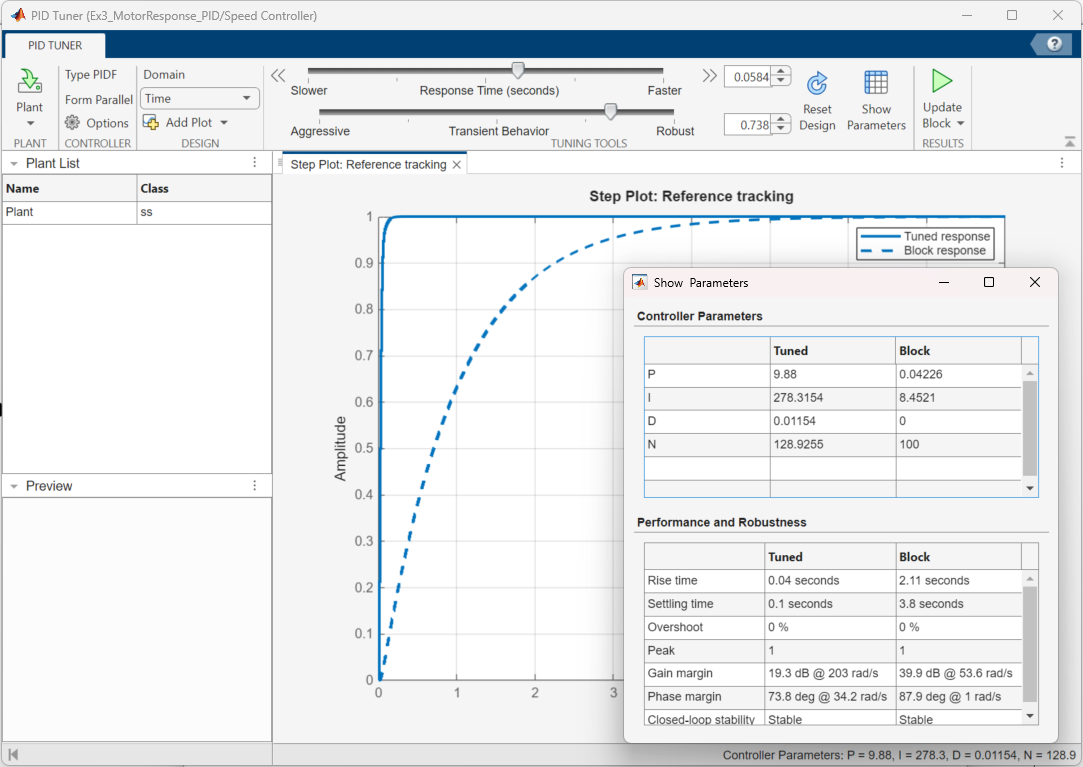

Once done. Simulate your model and record the model output.

%save the parameters back to the variables
motor_param.P = str2double(string(get_param("Ex3_PID_Tuning/Speed Controller",'P')));
motor_param.I = str2double(string(get_param("Ex3_PID_Tuning/Speed Controller",'I')));
motor_param.D = str2double(string(get_param("Ex3_PID_Tuning/Speed Controller",'D')));
motor_param.N = str2double(string(get_param("Ex3_PID_Tuning/Speed Controller",'N')));

Now, we can validate the tuned PID controller on the Hardware. Compare the simulated response with the actual response by switching the variant model to drive the real motor. Run the model in external mode (set solver to discrete time solver, timestep=0.01s) and compare the motor speed with the simulation using the Data Inspector ([https://www.mathworks.com/help/simulink/slref/simulationdatainspector.html](https://www.mathworks.com/help/simulink/slref/simulationdatainspector.html)).

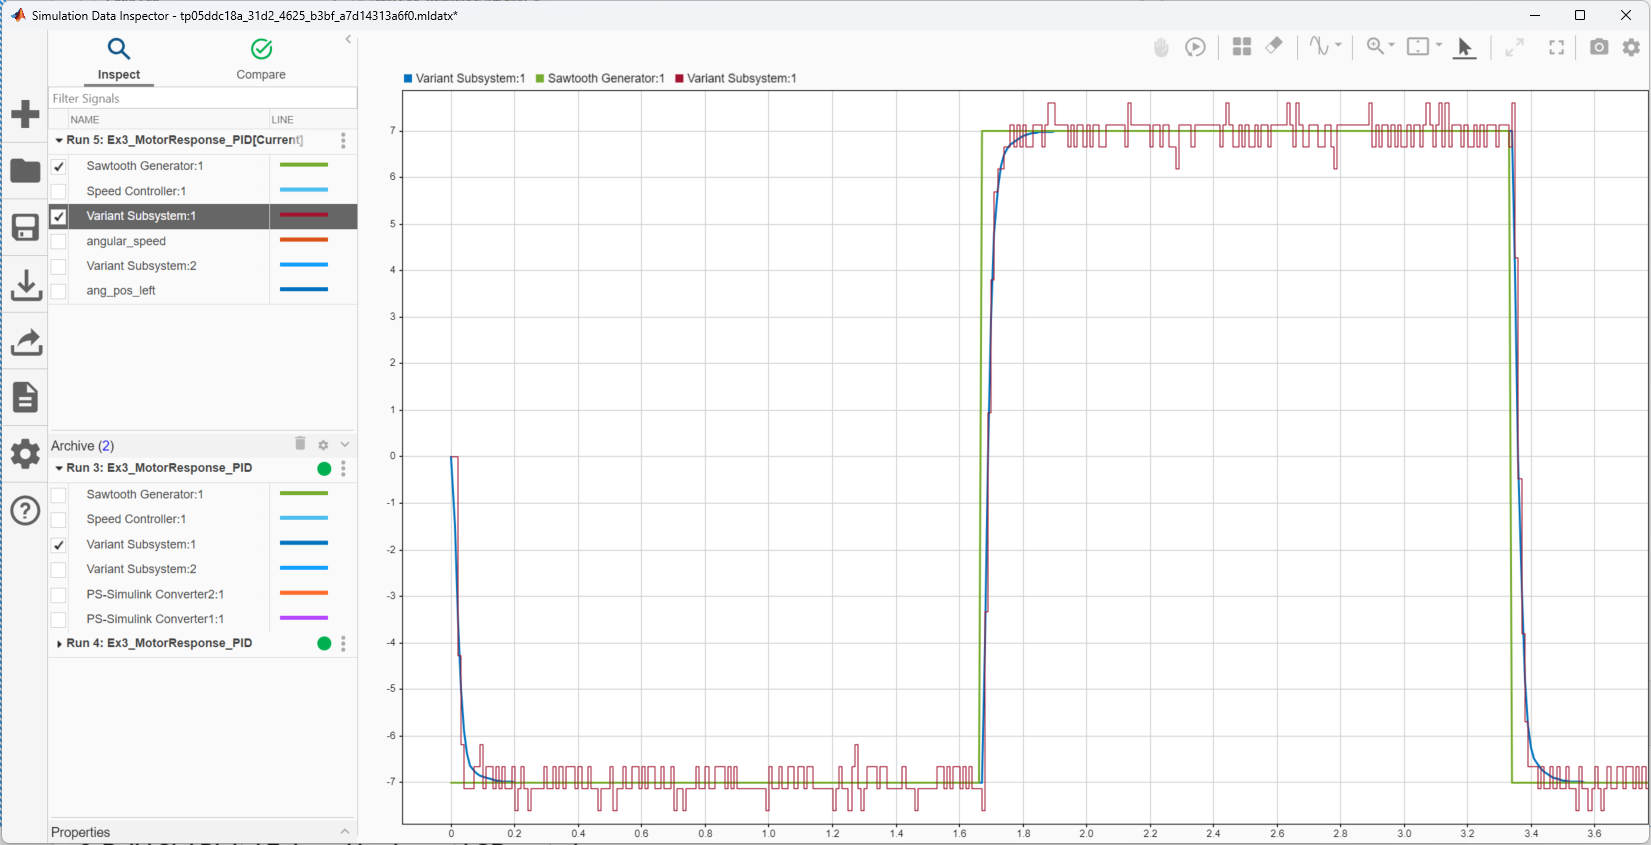

If the result is fine, we can save the optimized parameters and do the optimization for the second motor by reapeating the steps in section 1.7. 

motor="left";
%save the optimized parameters for later reuse
if motor=="left"
    save("optimized_param_mot_left.mat","motor_param",'-mat')
elseif motor=="right"
    save("optimized_param_mot_right.mat","motor_param",'-mat')
end


At this stage we have successfully optimized the parameters for both motors and saved them in individual .mat files. To simplify future reuse, we store them in a single .mat file.

load('optimized_param_mot_left.mat')
motor_left=motor_param;
load('optimized_param_mot_right.mat')
motor_right=motor_param;

gear_ratio=motor_param.gear_ratio;

% you have to be in the Models folder to save the parameters

save("./Data/Configs/Sigi_MathWorks.mat","motor_param","motor_right","motor_left",'-mat')